clear;clc;close all

## Define Constants

mu = 3.986004418e5; %398800; % [km^3/s^2] Gravitational Constant
r0 = 6678; % [km] nominal orbit radius
w0 = sqrt(mu/r0^3);
% Constants for the output vector
Re = 6378; % [km]
we = 2*pi/86400; % [rad/s]
N = 12; % Number of ground stations
dt = 10; % [s]
Tf = 14000; % [s] Final time (one orbit)

## Nominal Trajectory

t = 0:dt:Tf;
xnom = [r0*cos(w0*t);
    -r0*w0*sin(w0*t);
    r0*sin(w0*t);
    r0*w0*cos(w0*t)];

## Linearized Perturbation

dx(:,1) = [0; 0.075; 0; -0.021]; % Initial state perturbation

for kk = 1:length(t)-1
    dx(:,kk+1) = (eye(4) + dt*A(xnom(:,kk),mu))*dx(:,kk);
end
xLin = xnom+dx; % Linear trajectory is nominal trajectory + perturbation

## Plotting States and Perturbations (Linear)

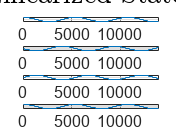

figure
ylabs = {'$X$','$\dot{X}$','$Y$','$\dot{Y}$'};
for kk = 1:4
    sb(kk) = subplot(4,1,kk);
    stairs(t,xLin(kk,:))
    grid on
    ylabel(ylabs{kk},'Interpreter','Latex','FontSize',14)
    axis padded
    xlim([0 Tf])
end
xlabel('Time [s]','Interpreter','Latex','FontSize',14)
linkaxes(sb,'x')
subplot(4,1,1)
title('Linearized States','Interpreter','Latex','FontSize',14)
saveas(gca,'LinStates.png')

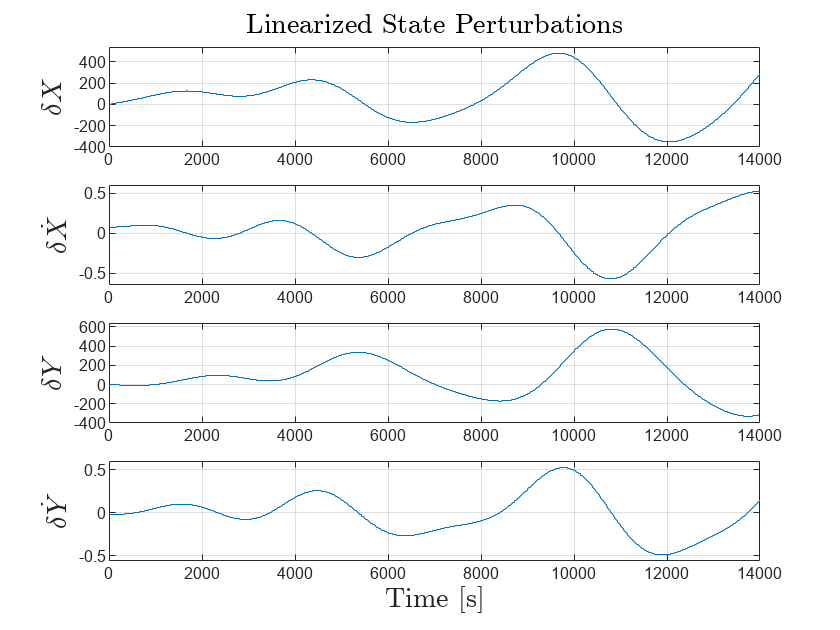


figure
ylabs = {'$\delta X$','$\delta \dot{X}$','$\delta Y$','$\delta \dot{Y}$'};
for kk = 1:4
    sb(kk) = subplot(4,1,kk);
    stairs(t,dx(kk,:))
    grid on
    ylabel(ylabs{kk},'Interpreter','Latex','FontSize',14)
    axis padded
    xlim([0 Tf])
end
xlabel('Time [s]','Interpreter','Latex','FontSize',14)
linkaxes(sb,'x')
subplot(4,1,1)
title('Linearized State Perturbations','Interpreter','Latex','FontSize',14)
saveas(gca,'LinStatePert.png')

## on-Linear States

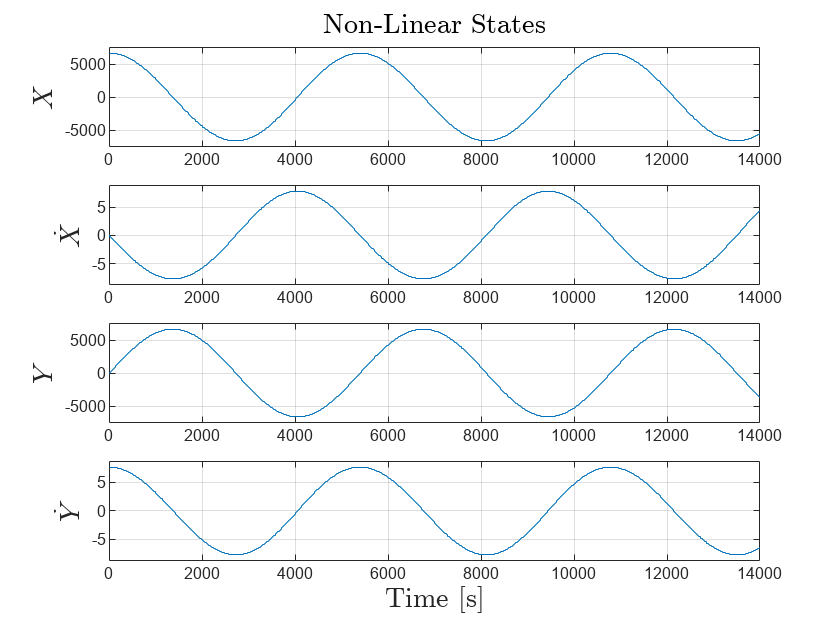

opts = odeset('RelTol',1e-12,'AbsTol',1e-5);
[tNL,xNL] = ode45(@nLEQ,t,[r0;0;0;r0*w0]+[0; 0.075; 0; -0.021],opts);
xNL = xNL';

figure
ylabs = {'$X$','$\dot{X}$','$Y$','$\dot{Y}$'};
for kk = 1:4
    sb(kk) = subplot(4,1,kk);
    stairs(tNL,xNL(kk,:))
    grid on
    ylabel(ylabs{kk},'Interpreter','Latex','FontSize',14)
    axis padded
    xlim([0 Tf])
end
xlabel('Time [s]','Interpreter','Latex','FontSize',14)
linkaxes(sb,'x')
subplot(4,1,1)
title('Non-Linear States','Interpreter','Latex','FontSize',14)
saveas(gca,'NLStates.png')

## Non-Linear Outptus

visSatsNL = diag(1:12)*ones(N,size(t,2));
for kk = 1:length(t)
    for nn = 1:12
        thi = wrapTo2Pi((nn - 1)*pi/6); % Theta 0 for ground station i
        Xis = Re*cos(we*t(kk)+thi);
        Yis = Re*sin(we*t(kk)+thi);
        dXis = -Re*we*sin(we*t(kk)+thi);
        dYis = Re*we*cos(we*t(kk)+thi);
        x_stat(:,kk,nn) = [Xis;dXis;Yis;dYis];

        thLim = we*t(kk)+thi;

        yNL(:,kk,nn) = [sqrt((xNL(1,kk)-Xis)^2+(xNL(3,kk)-Yis)^2);
                    ((xNL(1,kk)-Xis)*(xNL(2,kk)-dXis)+(xNL(3,kk)-Yis)*(xNL(4,kk)-dYis))/(sqrt((xNL(1,kk)-Xis)^2+(xNL(3,kk)-Yis)^2));
                    atan2((xNL(3,kk)-Yis),(xNL(1,kk)-Xis))];
        
        inView = and(angdiff(yNL(3,kk,nn),thLim) <= pi/2,angdiff(yNL(3,kk,nn),thLim) >= -pi/2);
        if ~inView
            yNL(:,kk,nn) = [NaN;NaN;NaN];
            visSatsNL(nn,kk) = NaN;
        end
    end
end

linType = {'x','o','square','^'};
ylabs = {'$\rho^i$ [km]','$\dot{\rho}^i$ [km/s]','$\phi^i$ [rad]','Station ID'};
figure
for kk = 1:3
    sb(kk) = subplot(4,1,kk);
    for nn = 1:12
        plot(tNL,yNL(kk,:,nn),linType{kk})
        hold on
    end
    ylabel(ylabs{kk},'Interpreter','Latex','FontSize',14)
    grid on
    hold off
    axis padded
    xlim([0 Tf])
end
sb(4) = subplot(4,1,4);
plot(tNL,visSatsNL,linType{4})
ylim([1 12])
grid on
ylabel(ylabs{4},'Interpreter','Latex','FontSize',11)
linkaxes(sb,'x')
xlabel('Time [s]','Interpreter','Latex','FontSize',14)
subplot(4,1,1)
title('Non-Linear Tracking Station Outputs','Interpreter','Latex','FontSize',14)
saveas(gca,'NLOut.png')


## Outputs and Ground Stations (Linear)

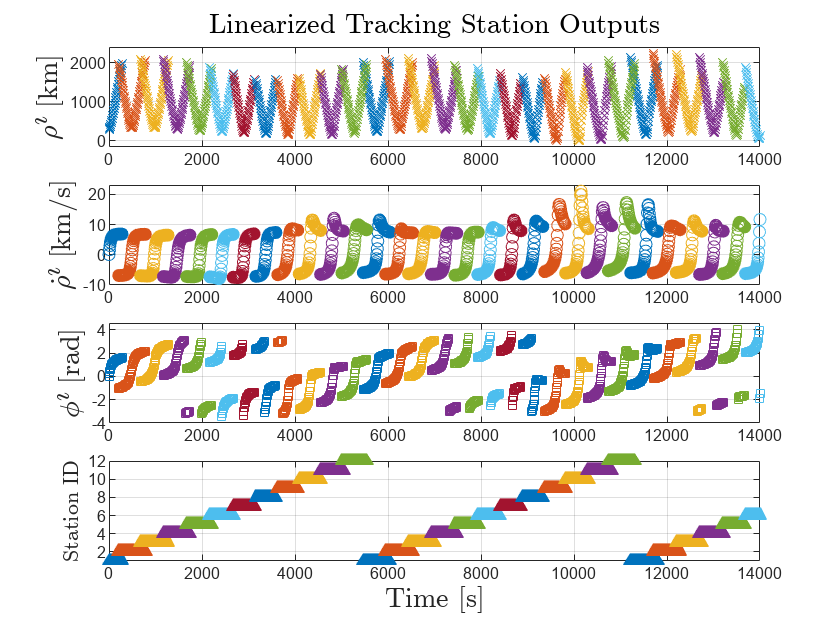

visSats = diag(1:12)*ones(N,size(t,2));
for kk = 1:length(t)
    for nn = 1:12
        thi = wrapTo2Pi((nn - 1)*pi/6); % Theta 0 for ground station i
        Xis = Re*cos(we*t(kk)+thi);
        Yis = Re*sin(we*t(kk)+thi);
        dXis = -Re*we*sin(we*t(kk)+thi);
        dYis = Re*we*cos(we*t(kk)+thi);
        x_stat(:,kk,nn) = [Xis;dXis;Yis;dYis];

        thLim = we*t(kk)+thi;
        
        ynom(:,kk,nn) = [sqrt((xnom(1,kk)-Xis)^2+(xnom(3,kk)-Yis)^2);
                    ((xnom(1,kk)-Xis)*(xnom(2,kk)-dXis)+(xnom(3,kk)-Yis)*(xnom(4,kk)-dYis))/(sqrt((xnom(1,kk)-Xis)^2+(xnom(3,kk)-Yis)^2));
                    atan2((xnom(3,kk)-Yis),(xnom(1,kk)-Xis))];

        dy(:,kk,nn) = C(xnom(:,kk),t(kk),nn)*dx(:,kk); % Get measurement perturbation

        yLin(:,kk,nn) = ynom(:,kk,nn) + dy(:,kk,nn);

        inView = and(angdiff(yNL(3,kk,nn),thLim) <= pi/2,angdiff(yNL(3,kk,nn),thLim) >= -pi/2);
        if ~inView
            yLin(:,kk,nn) = [NaN;NaN;NaN];
            visSats(nn,kk) = NaN;
        end
    end
end

linType = {'x','o','square','^'};
ylabs = {'$\rho^i$ [km]','$\dot{\rho}^i$ [km/s]','$\phi^i$ [rad]','Station ID'};
figure
for kk = 1:3
    sb(kk) = subplot(4,1,kk);
    for nn = 1:12
        plot(t,yLin(kk,:,nn),linType{kk})
        hold on
    end
    ylabel(ylabs{kk},'Interpreter','Latex','FontSize',14)
    grid on
    hold off
    axis padded
    xlim([0 Tf])
end
sb(4) = subplot(4,1,4);
plot(t,visSats,linType{4})
ylim([1 12])
grid on
ylabel(ylabs{4},'Interpreter','Latex','FontSize',11)
linkaxes(sb,'x')
xlabel('Time [s]','Interpreter','Latex','FontSize',14)
subplot(4,1,1)
title('Linearized Tracking Station Outputs','Interpreter','Latex','FontSize',14)
saveas(gca,'LinOut.png')

## Non-Linear States

opts = odeset('RelTol',1e-12,'AbsTol',1e-5);
[tNL,xNL] = ode45(@nLEQ,t,[r0;0;0;r0*w0]+[0; 0.075; 0; -0.021],opts);
xNL = xNL';

figure
ylabs = {'$X$','$\dot{X}$','$Y$','$\dot{Y}$'};
for kk = 1:4
    sb(kk) = subplot(4,1,kk);
    stairs(tNL,xNL(kk,:))
    grid on
    ylabel(ylabs{kk},'Interpreter','Latex','FontSize',14)
    axis padded
    xlim([0 Tf])
end
xlabel('Time [s]','Interpreter','Latex','FontSize',14)
linkaxes(sb,'x')
subplot(4,1,1)
title('Non-Linear States','Interpreter','Latex','FontSize',14)
saveas(gca,'NLStates.png')

## Non-Linear Outptus

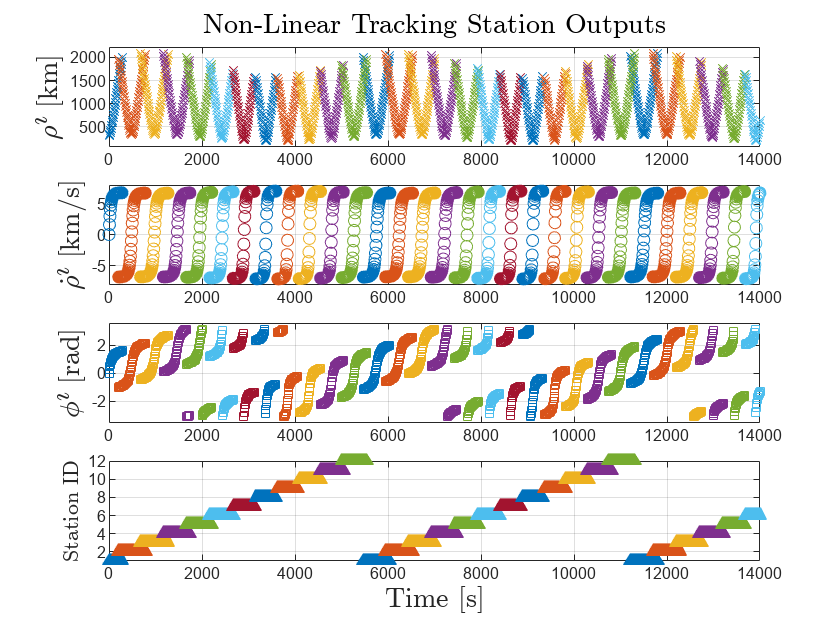

visSatsNL = diag(1:12)*ones(N,size(t,2));
for kk = 1:length(t)
    for nn = 1:12
        thi = wrapTo2Pi((nn - 1)*pi/6); % Theta 0 for ground station i
        Xis = Re*cos(we*t(kk)+thi);
        Yis = Re*sin(we*t(kk)+thi);
        dXis = -Re*we*sin(we*t(kk)+thi);
        dYis = Re*we*cos(we*t(kk)+thi);
        x_stat(:,kk,nn) = [Xis;dXis;Yis;dYis];

        thLim = we*t(kk)+thi;

        yNL(:,kk,nn) = [sqrt((xNL(1,kk)-Xis)^2+(xNL(3,kk)-Yis)^2);
                    ((xNL(1,kk)-Xis)*(xNL(2,kk)-dXis)+(xNL(3,kk)-Yis)*(xNL(4,kk)-dYis))/(sqrt((xNL(1,kk)-Xis)^2+(xNL(3,kk)-Yis)^2));
                    atan2((xNL(3,kk)-Yis),(xNL(1,kk)-Xis))];
        
        inView = and(angdiff(yNL(3,kk,nn),thLim) <= pi/2,angdiff(yNL(3,kk,nn),thLim) >= -pi/2);
        if ~inView
            yNL(:,kk,nn) = [NaN;NaN;NaN];
            visSatsNL(nn,kk) = NaN;
        end
    end
end

linType = {'x','o','square','^'};
ylabs = {'$\rho^i$ [km]','$\dot{\rho}^i$ [km/s]','$\phi^i$ [rad]','Station ID'};
figure
for kk = 1:3
    sb(kk) = subplot(4,1,kk);
    for nn = 1:12
        plot(tNL,yNL(kk,:,nn),linType{kk})
        hold on
    end
    ylabel(ylabs{kk},'Interpreter','Latex','FontSize',14)
    grid on
    hold off
    axis padded
    xlim([0 Tf])
end
sb(4) = subplot(4,1,4);
plot(tNL,visSatsNL,linType{4})
ylim([1 12])
grid on
ylabel(ylabs{4},'Interpreter','Latex','FontSize',11)
linkaxes(sb,'x')
xlabel('Time [s]','Interpreter','Latex','FontSize',14)
subplot(4,1,1)
title('Non-Linear Tracking Station Outputs','Interpreter','Latex','FontSize',14)
saveas(gca,'NLOut.png')

## Short Video (Linear)

vidColors = {[0 0.4470 0.7410],[0.8500 0.3250 0.0980],[0.9290 0.6940 0.1250],[0.4940 0.1840 0.5560],[0.4660 0.6740 0.1880],[0.3010 0.7450 0.9330],[0.6350 0.0780 0.1840],[0 0.4470 0.7410],[0.8500 0.3250 0.0980],[0.9290 0.6940 0.1250],[0.4940 0.1840 0.5560],[0.4660 0.6740 0.1880],[0.3010 0.7450 0.9330],[0.6350 0.0780 0.1840]};
v = VideoWriter('Video-Linear.avi');
open(v)
figure('Renderer', 'painters', 'Position', [10 10 1920 1080])
for kk = 1:size(t,2)
    tiledlayout(4,8)
    nexttile(1,[4,4])
    p = nsidedpoly(1000, 'Center', [0 0], 'Radius', 6300);
    plot(p, 'FaceColor', 'none')
    hold on
    for nn = 1:N
        plot(x_stat(1,kk,nn),x_stat(3,kk,nn),'o','Color',vidColors{nn},'LineWidth',2)
        if ~isnan(visSats(nn,kk))
            plot([x_stat(1,kk,nn) xLin(1,kk)],[x_stat(3,kk,nn) xLin(3,kk)],'--','Color',vidColors{nn})
        end
    end
    plot(xLin(1,kk),xLin(3,kk),'square','MarkerSize',8,'LineWidth',4,'Color','k')   
    grid on 
    axis equal
    hold off
    xlabel('X [km]','Interpreter','Latex','FontSize',14)
    ylabel('Y [km]','Interpreter','Latex','FontSize',14)
    title('Linearized Spacecraft Orbit','Interpreter','Latex','FontSize',14)
    linType = {'x','o','square','^'};
    ylabs = {'$\rho^i$ [km]','$\dot{\rho}^i$ [km/s]','$\phi^i$ [rad]','Station ID'};
    for jj = 1:3
        nexttile([1,4])
        for nn = 1:12
            plot(t(1:kk),yLin(jj,1:kk,nn),linType{jj})
            hold on
        end
        ylabel(ylabs{jj},'Interpreter','Latex','FontSize',14)
        grid on
        hold off
        if jj == 1
            title('Linearized Tracking Station Outputs','Interpreter','Latex','FontSize',14)
        end
        ylim([min(min(yLin(jj,:,:))) max(max(yLin(jj,:,:)))])
        xlim([0 Tf])
    end
    nexttile([1,4])
    plot(t(1:kk),visSats(:,1:kk),linType{4})
    ylim([1 12])
    xlim([0 Tf])
    grid on
    ylabel(ylabs{4},'Interpreter','Latex','FontSize',11)
    xlabel('Time [s]','Interpreter','Latex','FontSize',14)
    frame = getframe(gcf);
    writeVideo(v,frame);
end
close(v);

## Short Video (Non-Linear)

vidColors = {[0 0.4470 0.7410],[0.8500 0.3250 0.0980],[0.9290 0.6940 0.1250],[0.4940 0.1840 0.5560],[0.4660 0.6740 0.1880],[0.3010 0.7450 0.9330],[0.6350 0.0780 0.1840],[0 0.4470 0.7410],[0.8500 0.3250 0.0980],[0.9290 0.6940 0.1250],[0.4940 0.1840 0.5560],[0.4660 0.6740 0.1880],[0.3010 0.7450 0.9330],[0.6350 0.0780 0.1840]};
v = VideoWriter('Video-NonLinear.avi');
open(v)
figure('Renderer', 'painters', 'Position', [10 10 1920 1080])
for kk = 1:size(t,2)
    tiledlayout(4,8)
    nexttile(1,[4,4])
    p = nsidedpoly(1000, 'Center', [0 0], 'Radius', 6300);
    plot(p, 'FaceColor', 'none')
    hold on
    for nn = 1:N
        plot(x_stat(1,kk,nn),x_stat(3,kk,nn),'o','Color',vidColors{nn},'LineWidth',2)
        if ~isnan(visSats(nn,kk))
            plot([x_stat(1,kk,nn) xNL(1,kk)],[x_stat(3,kk,nn) xNL(3,kk)],'--','Color',vidColors{nn})
        end
    end
    plot(xNL(1,kk),xNL(3,kk),'square','MarkerSize',8,'LineWidth',4,'Color','k')   
    grid on 
    axis equal
    hold off
    xlabel('X [km]','Interpreter','Latex','FontSize',14)
    ylabel('Y [km]','Interpreter','Latex','FontSize',14)
    title('Non-Linear Spacecraft Orbit','Interpreter','Latex','FontSize',14)
    linType = {'x','o','square','^'};
    ylabs = {'$\rho^i$ [km]','$\dot{\rho}^i$ [km/s]','$\phi^i$ [rad]','Station ID'};
    for jj = 1:3
        nexttile([1,4])
        for nn = 1:12
            plot(tNL(1:kk),yNL(jj,1:kk,nn),linType{jj})
            hold on
        end
        ylabel(ylabs{jj},'Interpreter','Latex','FontSize',14)
        grid on
        hold off
        if jj == 1
            title('Non-Linear Tracking Station Outputs','Interpreter','Latex','FontSize',14)
        end
        ylim([min(min(yNL(jj,:,:))) max(max(yNL(jj,:,:)))])
        xlim([0 Tf])
    end
    nexttile([1,4])
    plot(tNL(1:kk),visSatsNL(:,1:kk),linType{4})
    ylim([1 12])
    xlim([0 Tf])
    grid on
    ylabel(ylabs{4},'Interpreter','Latex','FontSize',11)
    xlabel('Time [s]','Interpreter','Latex','FontSize',14)
    frame = getframe(gcf);
    writeVideo(v,frame);
end
close(v);

## **Utility Functions**

function out = A(x,mu)
    r2 = x(1)^2 + x(3)^2; % This is r^2
    
    f2x1 = -mu*((r2^(3/2))-(3*x(1)^2*sqrt(r2)))/(r2^3);
    f4x3 = -mu*((r2^(3/2))-(3*x(3)^2*sqrt(r2)))/(r2^3);
    f4x1 = (3*mu*x(3)*x(1))/(r2^(5/2));
    f2x3 = (3*mu*x(3)*x(1))/(r2^(5/2));
    
    out = [0   1   0  0
        f2x1 0 f2x3 0;
         0   0   0  1;
        f4x1 0 f4x3 0];
end

function out = C(x,t,i)
    Re = 6378; % [km]
    we = 2*pi/86400; % [rad/s]
    thi = (i - 1)*pi/6; % Theta 0 for ground station i
    Xis = Re*cos(we*t+thi);
    Yis = Re*sin(we*t+thi);
    
    dXis = -Re*we*sin(we*t+thi);
    dYis = Re*we*cos(we*t+thi);
    
    sq = sqrt((x(1) - Xis)^2 + (x(3)-Yis)^2);
    
    h1x1 = (x(1)-Xis)/sq;
    h1x3 = (x(3)-Yis)/sq;
    h2x1 = (x(2)-dXis)/sq - (x(1)-Xis)*(x(2)-dXis)/sq^3 - (x(1)-Xis)*(x(3)-Yis)*(x(4)-dYis)/sq^3;
    h2x2 = (x(1)-Xis)/sq;
    h2x3 = (x(4)-dYis)/sq - (x(3)-Yis)*(x(4)-dYis)/sq^3 - (x(1)-Xis)*(x(3)-Yis)*(x(2)-dXis)/sq^3;
    h2x4 = (x(3)-Yis)/sq;
    h3x1 = -(x(3)-Yis)/sq^2;
    h3x3 = (x(1)-Xis)/sq^2;
    
    out = [h1x1 0 h1x3 0;
           h2x1 h2x2 h2x3 h2x4;
           h3x1 0 h3x3 0];
end

function dxdt = nLEQ(t,x)
    mu = 3.986004418e5;
    dxdt = [x(2);
    -(mu*x(1))/(x(1)^2+x(3)^2)^(3/2);
    x(4);
    -(mu*x(3))/(x(1)^2+x(3)^2)^(3/2)];
end